%% Vorbereitung
close all;
clear;
clc;

% Dateien anpassen:
emg_data = load('C:\Users\Niklas\sciebo - Burczyk, Niklas (nibur001@fh-dortmund.de)@fh-dortmund.sciebo.de2\Master\Semester 1\PA\Proband4\F_3\recorded_data_1751984315237.txt');  % [timestamp, emg_value]
pred_data = load('C:\Users\Niklas\sciebo - Burczyk, Niklas (nibur001@fh-dortmund.de)@fh-dortmund.sciebo.de2\Master\Semester 1\PA\Proband4\F_3\prediction_1751984315305.txt'); % [timestamp, prediction_class]

emg_timestamps = emg_data(:,1);
emg_values = emg_data(:,2);

pred_timestamps = pred_data(:,1);
pred_classes = pred_data(:,2);

% Synchronisation: Vorhersage an EMG Zeitpunkte anpassen
pred_synced = zeros(size(emg_timestamps));
for i = 1:length(emg_timestamps)
    idx = find(pred_timestamps >= emg_timestamps(i), 1, 'first');
    if isempty(idx), idx = length(pred_timestamps); end
    pred_synced(i) = pred_classes(idx);
end

time_sec = (emg_timestamps - emg_timestamps(1))/1000;

% Aufnahme max. 30s begrenzen
max_duration_s = 30;
valid_idx = time_sec <= max_duration_s;

time_sec = time_sec(valid_idx);
emg_values = emg_values(valid_idx);
pred_synced = pred_synced(valid_idx);

% EMG plotten zur Auswahl der Aktionsphase
figure;
plot(time_sec, emg_values, 'k');
title('EMG-Rohdaten: Bitte Aktionsphase per 2 Mausklicks auswählen');
xlabel('Zeit (s)');
ylabel('EMG-Amplitude');
grid on;
xlim([0 max_duration_s]);

fprintf('Bitte 2 Mausklicks wählen: Start und Ende der Aktionsphase (Faust oder Pinzette)\n');

Bitte 2 Mausklicks wählen: Start und Ende der Aktionsphase (Faust oder Pinzette)


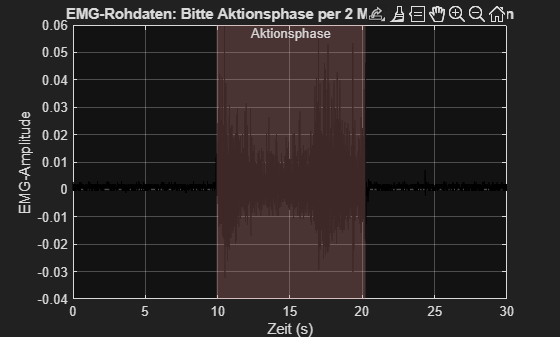

[x, ~] = ginput(2);
x = sort(x);

hold on;
yl = ylim;
fill([x(1) x(2) x(2) x(1)], [yl(1) yl(1) yl(2) yl(2)], [0.8 0.5 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
text(mean(x), yl(2)*0.95, 'Aktionsphase', 'HorizontalAlignment', 'center');


% Erwartete Labels initialisieren: 10s offen vor und nach Aktion + rest offen
true_labels = ones(size(time_sec)); % Alles Hand offen (1)

% Aktionslabel: 0=Faust, 2=Pinzette, 1=Offen (hier anpassen!)
aktions_label = 0; % Beispiel: Faust

% Setze Aktionsphase
true_labels(time_sec >= x(1) & time_sec <= x(2)) = aktions_label;

% Optional: sicherstellen, dass Anfang und Ende jeweils offen (10s)
% Falls Aufnahme länger als 30s: Beschränkt durch valid_idx oben.

% Genauigkeit berechnen
matching = (pred_synced == true_labels);
accuracy = mean(matching)*100;

fprintf('\nGesamtgenauigkeit: %.2f%%\n', accuracy);


Gesamtgenauigkeit: 80.33%


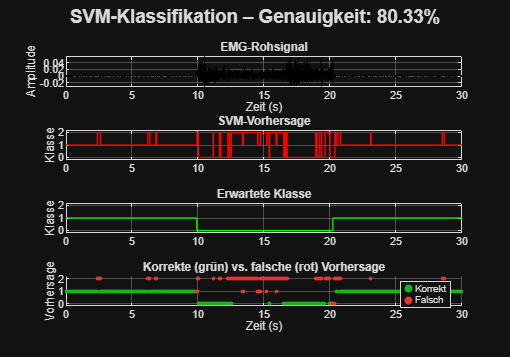


% Visualisierung
figure('Position',[100 100 1000 700]);

subplot(4,1,1);
plot(time_sec, emg_values, 'k');
title('EMG-Rohsignal');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;
xlim([0 max_duration_s]);

subplot(4,1,2);
stairs(time_sec, pred_synced, 'r', 'LineWidth', 1);
title('SVM-Vorhersage');
ylabel('Klasse');
yticks([0 1 2]);
ylim([-0.2 2.2]);
grid on;
xlim([0 max_duration_s]);

subplot(4,1,3);
stairs(time_sec, true_labels, 'g', 'LineWidth', 1);
title('Erwartete Klasse');
ylabel('Klasse');
yticks([0 1 2]);
ylim([-0.2 2.2]);
grid on;
xlim([0 max_duration_s]);

subplot(4,1,4);
hold on;
correct_idx = find(matching);
wrong_idx = find(~matching);
scatter(time_sec(correct_idx), pred_synced(correct_idx), 8, [0.1 0.7 0.1], 'filled');
scatter(time_sec(wrong_idx), pred_synced(wrong_idx), 8, [0.9 0.2 0.2], 'filled');
title('Korrekte (grün) vs. falsche (rot) Vorhersage');
xlabel('Zeit (s)');
ylabel('Vorhersage');
yticks([0 1 2]);
ylim([-0.2 2.2]);
legend('Korrekt','Falsch');
grid on;
xlim([0 max_duration_s]);

sgtitle(sprintf('SVM-Klassifikation – Genauigkeit: %.2f%%', accuracy),'FontSize',14,'FontWeight','bold');